# Stackelberg Game

The Stackelberg equilibrium (SE) is defivned as follows:


$$	r^{\star} = \max_{r} \min_{s_i \in R_{i}(r), i\in\{BS_1,BS_2\}} U_{IRS}(r,s_1,s_2)
$$


and $$R_i(r)$$ is the BSs best response which is obtained by maximizing exact potential function for a fixed $$r$$.

%% Before we start
% clc
close all
addpath('C:\Users\Asus irG\OneDrive\Documents\MATLAB\Thesis numerical analysis\RIS-Sharing-Scenario-main\common methods') % You need to change the address in case you run it on your computer

## NE using EPG in followres level

### Parameters

%% parameters
N1 = 2 ;                                % No. first Basestations users
N2 = 2 ;                                 % No. first Basestations users
R1 = 10 ;                                % BS1 user area center radius
R2 = 10 ;                                % BS2 user area center radius 
R = [R1 ; R2] ;
N_i = 24 ;                                % No.  IRS elements
q_t = 1/12 ;                              % Quantization step-size
N_iter = 10000 ;
SV = 11 ;                                  % Scenario Variable
P_T = (10^(40/10)) * 1e-3 ;                 % BS power
% [x0,y0,z0] = deal(50,20,0) ;              % user area center
[x1,y1,z1] = deal(0,0,0) ;                % BS1 location
[x2,y2,z2] = deal(100,10,0) ;             % BS2 location
[x_i,y_i,z_i] = deal(50,30,10) ;          % IRS location
M_t = 1 ;                                 % No. of transmitter antennas
M_r = 1 ;                                 % No. of receiver antennas
d_IB = 100 ; 
alpha_d = 3.76 ; 
alpha_r = 2 ; 
BW = 10e7 ; 
noise_power = (10^(-114/10)) ;            % -169dbm/Hz
epsilon = 0.05 ; 
interference = 0 ;                      % Interference between two BSs.
StepSize = 0.001 * 1 ;
r_0 = 0.1 ;
r = 0.1 ; 

%% users location
x = zeros(N1 + N2,1) ; 
y = zeros(N1 + N2,1) ; 
z = 1.5 * ones(N1 + N2,1) ; 
x(1 : N1,1) = 35 ; 
x(N1 + 1 : N2 + N1) = 55 ; 
y(1 : N1,1) = 25 ; 
y(N1 + 1 : N2 + N1) = 10 ; 

### Utility vs distance

%% Calculating Rates
rate = zeros(ceil(1/q_t) + 1 , ceil(1/q_t) + 1 , 2 , SV) ;
EPG_final_rate = zeros(2,SV) ; 
EPG_final_utility = zeros(2,SV) ; 
Random_final_utility = zeros(2,SV) ; 
RIS_final_utility = zeros(SV , 1) ;
RIS_random_utility=zeros(SV,1) ;
Direct_utility = zeros(2,SV) ; 
step = 1 ;     
start = 8 ;   
m = repmat('.', 1, SV) ; 
tic
for d = start + 0 * step : step : start + (SV-1) * step
    m(1 + floor((d-start)/step)) = '|' ; 
    disp(m)
    y(1:N1) = d ; 
    i = 1 + floor((d-start)/step) ; 
    for j = 1 : N_iter
    
        [~, rate(:, :, :, i)] = PotentialGame(M_t, M_r, N1, N2, N_i, P_T, x, y, z, x1, y1, z1,...
                                x2, y2, z2, x_i, y_i, z_i, alpha_d, alpha_r, noise_power, 1,...
                                R, r, q_t, interference, epsilon) ;
        r_0 = 0.1 ;
        StepSize = 0.05 ;
        r = r_0 ;
        N_i_0 = zeros(2, 1) ;
        N_i_star = zeros(2, 1) ;
        epsilon  = 0.0002 ;
        
        utility = zeros(ceil(1/q_t) + 1,ceil(1/q_t) + 1,2) ;
        EPG_utility = zeros(ceil(1/q_t)+1,ceil(1/q_t)+1,2) ; 
        N_i11 = [] ;
        N_i22 = [] ;
        u11 = [] ;
        u22 = [] ;
        while 1 == 1
            r = r + StepSize * 1 ;
            for s1 = 1:ceil(1/q_t)+1
                for s2 = 1:ceil(1/q_t)+1
                    N_i1 = floor((s1-1) * N_i * q_t) ;     % No. of elements allocated to BS1
                    N_i2 = floor((s2-1) * N_i * q_t) ;     % No. of elements allocated to BS2
                    EPG_utility(s1, s2, 1) = N1*rate(s1, s2, 1, i) - N_i1 * r ; 
                    EPG_utility(s1, s2, 2) = N2*rate(s1, s2, 2, i) - N_i2 * r ; 
                end            
            end
            F = sum(EPG_utility,3) ; 
            maximum = max(max(F)) ; 
            [s1_star,s2_star] = find(F == maximum) ;
            N_i_0 = N_i_star ;
            N_i_star = [floor((s1_star-1) * N_i * q_t) ; floor((s2_star-1) * N_i * q_t) ] ;     % No. of elements allocated to BS2
            N_i11 = [ N_i11 ; N_i_star(1) ] ;
            N_i22 = [ N_i22 ; N_i_star(2) ] ;
            u11 = [ u11 ; EPG_utility(s1_star, s2_star, 1) ] ;
            u22 = [ u22 ; EPG_utility(s1_star, s2_star, 2) ] ;
            %        r_0 = r ;
            %        r = r - StepSize * sign( N_i/2 - sum(N_i_star ,"all"))
            %        r = r + StepSize * sign(1 + sum(N_i_0 ,"all") - sum(N_i_star ,"all"))
            %        if sign(1 + sum(N_i_0 ,"all") - sum(N_i_star ,"all")) < 0
            %             StepSize= 0.5 * StepSize ;
            %        end
            %        abs(r * sum(N_i_star ,"all") - r_0 * sum(N_i_0 ,"all"))
            %        if abs(r * sum(N_i_star ,"all") - r_0 * sum(N_i_0 ,"all")) < epsilon
            %            break ;
            %        end
            if sum( N_i_star , "all" ) == 0
                break ;
            end
        end
%         u11
%         u22
    RIS_utility=(r_0 + StepSize * 1 : StepSize : r + epsilon)'.*(N_i11 + N_i22);
    maximum = find(RIS_utility==local_maxima(RIS_utility , 0.2) , 1) ;
    maximum = r_0 + StepSize * maximum ;
    for s1 = 1:ceil(1/q_t)+1
            for s2 = 1:ceil(1/q_t)+1
                N_i1 = floor((s1-1) * N_i * q_t) ;     % No. of elements allocated to BS1
                N_i2 = floor((s2-1) * N_i * q_t) ;     % No. of elements allocated to BS2
                EPG_utility(s1, s2, 1) = N1 * rate(s1, s2, 1, i) - N_i1 * maximum ; 
                EPG_utility(s1, s2, 2) = N2 * rate(s1, s2, 2, i) - N_i2 * maximum ; 
            end            
    end
    F = sum(EPG_utility,3) ; 
    maximum = max(max(F)) ; 
    [s1_star,s2_star] = find(F == maximum) ;

    EPG_final_utility(1 , i) = EPG_final_utility(1 , i) + EPG_utility(s1_star, s2_star, 1) ;
    EPG_final_utility(2 , i) = EPG_final_utility(2 , i) + EPG_utility(s1_star, s2_star, 2) ;
    RIS_final_utility(i) = RIS_final_utility(i) + local_maxima(RIS_utility , 0.2) ; 
    
    % Random Pricing
    rr = (r-r_0) * rand(1) + r_0 ; 
    for s1 = 1:ceil(1/q_t)+1
            for s2 = 1:ceil(1/q_t)+1
                N_i1 = floor((s1-1) * N_i * q_t) ;     % No. of elements allocated to BS1
                N_i2 = floor((s2-1) * N_i * q_t) ;     % No. of elements allocated to BS2
                EPG_utility(s1, s2, 1) = N1 * rate(s1, s2, 1, i) - N_i1 * rr ; 
                EPG_utility(s1, s2, 2) = N2 * rate(s1, s2, 2, i) - N_i2 * rr ; 
            end            
    end
    F = sum(EPG_utility,3) ; 
    maximum = max(max(F)) ; 
    [s1_star,s2_star] = find(F == maximum) ;
    N_i1 = floor((s1_star-1) * N_i * q_t) ;     % No. of elements allocated to BS1
    N_i2 = floor((s2_star-1) * N_i * q_t) ;     % No. of elements allocated to BS2

    Random_final_utility(1 , i) = Random_final_utility(1 , i) + EPG_utility(s1_star, s2_star, 1) ;
    Random_final_utility(2 , i) = Random_final_utility(2 , i) + EPG_utility(s1_star, s2_star, 2) ;
    RIS_random_utility(i) = RIS_random_utility(i) + rr * (N_i1 + N_i2) ; 

    % NO RIS
    Direct_utility(: , i) = Direct_utility(: , i) + [EPG_utility(1, 1, 1);EPG_utility(1, 1, 2)] ;

%     EPG_final_utility
    end
end
toc

|..........
||.........
|||........
||||.......
|||||......
||||||.....
|||||||....
||||||||...
|||||||||..
||||||||||.
|||||||||||


EPG_final_utility =  EPG_final_utility /N_iter ;

Elapsed time is 131.108857 seconds.


RIS_final_utility = RIS_final_utility /N_iter ;
Random_final_utility =  Random_final_utility /N_iter ;
RIS_random_utility = RIS_random_utility /N_iter ;
Direct_utility = Direct_utility /N_iter ;

%% plot Utility
figure
tiledlayout(1,2)
nexttile
% draw BS1
set(gca,'FontName','Times New Roman','FontSize',11,'LineWidth',1.5) ; 
plot(0,0,'^','MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor','b','linewidth',1)
hold on
% draw BS2
plot(x2,y2,'^','MarkerSize',10,...
    'MarkerEdgeColor','r',...
    'MarkerFaceColor','r','linewidth',1)
% draw IRS
plot(x_i,y_i,'gs','MarkerSize',30,'linewidth',1)
% draw BS1 users
plot(x(1),y(1),'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
plot(x(1),y(1),'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% draw BS2 users
plot(x(N1+1),start,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% configs
title('User Location')
xlabel('x')
ylabel('y')
xlim([-5 150]) ; 
ylim([-5 50]) ; 
legend('BS1','BS2','IRS','UE1','UE1','UE2') ; 
grid on
nexttile
% draw results
plot(start : step : (SV-1) * step+start , EPG_final_utility(1 , 1 : SV) , 'b-*' , 'linewidth' , 1.5)
hold on
plot(start : step : (SV-1) * step+start , EPG_final_utility(2 , 1 : SV) , 'r-*' ,  'linewidth' , 1.5)
plot(start : step : (SV-1) * step+start ,  RIS_final_utility(1 : SV) , 'g-*' , 'linewidth' , 1.5)

plot(start : step : (SV-1) * step+start , Random_final_utility(1 , 1 : SV) , 'b-o' , 'linewidth' , 1.5)
plot(start : step : (SV-1) * step+start , Random_final_utility(2 , 1 : SV) , 'r-o' , 'linewidth' , 1.5)
plot(start : step : (SV-1) * step+start ,  RIS_random_utility(1 : SV) , 'g-o' , 'linewidth' , 1.5)

plot(start : step : (SV-1) * step+start , Direct_utility(1 , 1 : SV) , 'b--o' , 'linewidth' , 1.5)
plot(start : step : (SV-1) * step+start , Direct_utility(2 , 1 : SV) , 'r--o' ,  'linewidth' , 1.5)

legend('BS1 EPG' , 'BS2 EPG' , 'RIS SE' , 'BS1 Uniform' ,  'BS2 Uniform', 'RIS Uniform' , 'Direct') ; 
% legend('BS1 EPG' , 'BS1 RANDOM'...
%      , 'BS2 EPG' , 'BS2 RANDOM') ; 
% configs

grid on
set(gcf , 'color' , 'w');   % Set the figure background to white
title(['N = ' , num2str(N_i)])
xlabel('y')
ylabel('Utility')
xlim([start max((SV-1) * step+start , start+step)]) ; 
ylim([0 10]) ; 

### Utility vs Transmit power

%% Calculating Rates
rate = zeros(ceil(1/q_t) + 1 , ceil(1/q_t) + 1 , 2 , SV) ;
EPG_final_rate = zeros(2,SV) ; 
EPG_final_utility = zeros(2,SV) ; 
Random_final_utility = zeros(2,SV) ; 
RIS_final_utility = zeros(SV , 1) ;
RIS_random_utility=zeros(SV,1) ;
Direct_utility = zeros(2,SV) ; 
step = 2 ;     
start = 20 ;   
m = repmat('.', 1, SV) ; 
tic
for P_T = start + 0 * step : step : start + (SV-1) * step
    m(1 + floor((P_T-start)/step)) = '|' ; 
    disp(m)
    i = 1 + floor((P_T-start)/step) ; 
    for j = 1 : N_iter
    
        [~, rate(:, :, :, i)] = PotentialGame(M_t, M_r, N1, N2, N_i, (10^(P_T/10)) * 1e-3 , x, y, z, x1, y1, z1,...
                                x2, y2, z2, x_i, y_i, z_i, alpha_d, alpha_r, noise_power, 1,...
                                R, r, q_t, interference, epsilon) ;
        r_0 = 0.1 ;
        StepSize = 0.05 ;
        r = r_0 ;
        N_i_0 = zeros(2, 1) ;
        N_i_star = zeros(2, 1) ;
        epsilon  = 0.0002 ;
        
        utility = zeros(ceil(1/q_t) + 1,ceil(1/q_t) + 1,2) ;
        EPG_utility = zeros(ceil(1/q_t)+1,ceil(1/q_t)+1,2) ; 
        N_i11 = [] ;
        N_i22 = [] ;
        u11 = [] ;
        u22 = [] ;
        while 1 == 1
            r = r + StepSize * 1 ;
            for s1 = 1:ceil(1/q_t)+1
                for s2 = 1:ceil(1/q_t)+1
                    N_i1 = floor((s1-1) * N_i * q_t) ;     % No. of elements allocated to BS1
                    N_i2 = floor((s2-1) * N_i * q_t) ;     % No. of elements allocated to BS2
                    EPG_utility(s1, s2, 1) = N1*rate(s1, s2, 1, i) - N_i1 * r ; 
                    EPG_utility(s1, s2, 2) = N2*rate(s1, s2, 2, i) - N_i2 * r ; 
                end            
            end
            F = sum(EPG_utility,3) ; 
            maximum = max(max(F)) ; 
            [s1_star,s2_star] = find(F == maximum) ;
            N_i_0 = N_i_star ;
            N_i_star = [floor((s1_star-1) * N_i * q_t) ; floor((s2_star-1) * N_i * q_t) ] ;     % No. of elements allocated to BS2
            N_i11 = [ N_i11 ; N_i_star(1) ] ;
            N_i22 = [ N_i22 ; N_i_star(2) ] ;
            u11 = [ u11 ; EPG_utility(s1_star, s2_star, 1) ] ;
            u22 = [ u22 ; EPG_utility(s1_star, s2_star, 2) ] ;
            %        r_0 = r ;
            %        r = r - StepSize * sign( N_i/2 - sum(N_i_star ,"all"))
            %        r = r + StepSize * sign(1 + sum(N_i_0 ,"all") - sum(N_i_star ,"all"))
            %        if sign(1 + sum(N_i_0 ,"all") - sum(N_i_star ,"all")) < 0
            %             StepSize= 0.5 * StepSize ;
            %        end
            %        abs(r * sum(N_i_star ,"all") - r_0 * sum(N_i_0 ,"all"))
            %        if abs(r * sum(N_i_star ,"all") - r_0 * sum(N_i_0 ,"all")) < epsilon
            %            break ;
            %        end
            if sum( N_i_star , "all" ) == 0
                break ;
            end
        end
%         u11
%         u22
    RIS_utility=(r_0 + StepSize * 1 : StepSize : r + epsilon)'.*(N_i11 + N_i22);
    maximum = find(RIS_utility==local_maxima(RIS_utility , 0.2) , 1) ;
    maximum = r_0 + StepSize * maximum ;
    for s1 = 1:ceil(1/q_t)+1
            for s2 = 1:ceil(1/q_t)+1
                N_i1 = floor((s1-1) * N_i * q_t) ;     % No. of elements allocated to BS1
                N_i2 = floor((s2-1) * N_i * q_t) ;     % No. of elements allocated to BS2
                EPG_utility(s1, s2, 1) = N1 * rate(s1, s2, 1, i) - N_i1 * maximum ; 
                EPG_utility(s1, s2, 2) = N2 * rate(s1, s2, 2, i) - N_i2 * maximum ; 
            end            
    end
    F = sum(EPG_utility,3) ; 
    maximum = max(max(F)) ; 
    [s1_star,s2_star] = find(F == maximum) ;

    EPG_final_utility(1 , i) = EPG_final_utility(1 , i) + EPG_utility(s1_star, s2_star, 1) ;
    EPG_final_utility(2 , i) = EPG_final_utility(2 , i) + EPG_utility(s1_star, s2_star, 2) ;
    RIS_final_utility(i) = RIS_final_utility(i) + local_maxima(RIS_utility , 0.2) ; 
    
    % Random Pricing
    rr = (r-r_0) * rand(1) + r_0 ; 
    for s1 = 1:ceil(1/q_t)+1
            for s2 = 1:ceil(1/q_t)+1
                N_i1 = floor((s1-1) * N_i * q_t) ;     % No. of elements allocated to BS1
                N_i2 = floor((s2-1) * N_i * q_t) ;     % No. of elements allocated to BS2
                EPG_utility(s1, s2, 1) = N1 * rate(s1, s2, 1, i) - N_i1 * rr ; 
                EPG_utility(s1, s2, 2) = N2 * rate(s1, s2, 2, i) - N_i2 * rr ; 
            end            
    end
    F = sum(EPG_utility,3) ; 
    maximum = max(max(F)) ; 
    [s1_star,s2_star] = find(F == maximum) ;
    N_i1 = floor((s1_star-1) * N_i * q_t) ;     % No. of elements allocated to BS1
    N_i2 = floor((s2_star-1) * N_i * q_t) ;     % No. of elements allocated to BS2

    Random_final_utility(1 , i) = Random_final_utility(1 , i) + EPG_utility(s1_star, s2_star, 1) ;
    Random_final_utility(2 , i) = Random_final_utility(2 , i) + EPG_utility(s1_star, s2_star, 2) ;
    RIS_random_utility(i) = RIS_random_utility(i) + rr * (N_i1 + N_i2) ; 

    % NO RIS
    Direct_utility(: , i) = Direct_utility(: , i) + [EPG_utility(1, 1, 1);EPG_utility(1, 1, 2)] ;

%     EPG_final_utility
    end
end
toc

|..........
||.........
|||........
||||.......
|||||......
||||||.....
|||||||....
||||||||...
|||||||||..
||||||||||.
|||||||||||


EPG_final_utility =  EPG_final_utility /N_iter ;

Elapsed time is 287.112860 seconds.


RIS_final_utility = RIS_final_utility /N_iter ;
Random_final_utility =  Random_final_utility /N_iter ;
RIS_random_utility = RIS_random_utility /N_iter ;
Direct_utility = Direct_utility /N_iter ;

Fixes to make in the future

- rewrite the code to save only the so-far maximum of RIS utility and the price . 

- write a method as Stackelberg game which returns the SE and NE.

- Warnings

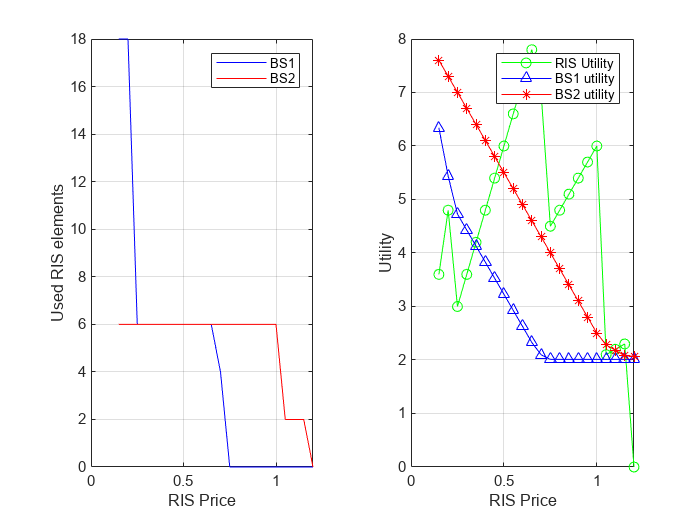

figure % Utility Versus R
tiledlayout(1,2)
nexttile
plot( r_0 + StepSize * 1 : StepSize : r + epsilon , N_i11 , 'b')
hold on
grid on
plot( r_0 + StepSize * 1 : StepSize : r + epsilon, N_i22 , 'r' )
xlabel('RIS Price')
ylabel('Used RIS elements')
legend( 'BS1 ', 'BS2 ' )
% plot( r_0 : StepSize : r , (N_i11 + N_i22) , 'r')
% size((r_0 + StepSize * 1 : StepSize : r + epsilon)')
% size(N_i22 )
nexttile
plot( r_0 + StepSize * 1 : StepSize : r + epsilon , (r_0 + StepSize * 1 : StepSize : r + epsilon)'.*(N_i11 + N_i22) , 'g-o')
hold on
grid on
plot(r_0 + StepSize * 1 : StepSize : r + epsilon,  u11(1 : end),'b-^' )
plot(r_0 + StepSize * 1 : StepSize : r + epsilon,  u22(1 : end) ,'r-*')
xlabel('RIS Price')
ylabel('Utility')
legend( 'RIS Utility', 'BS1 utility', 'BS2 utility' )
saveas(gcf,['RIS utility and elements used for y=', num2str(i)],'epsc')

% figure
% plot(N_i11 , u11  )

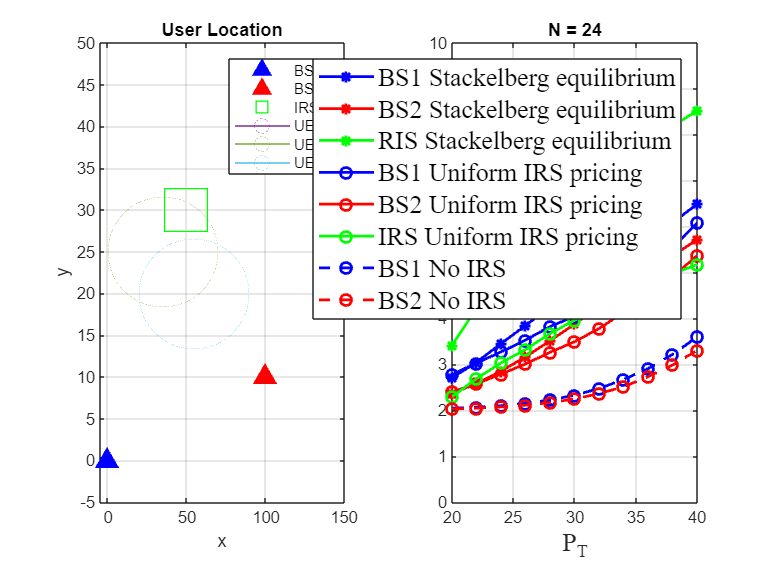

%% plot Utility
figure
tiledlayout(1,2)
nexttile
% draw BS1
set(gca,'FontName','Times New Roman','FontSize',11,'LineWidth',1.5) ; 
plot(0,0,'^','MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor','b','linewidth',1)
hold on
% draw BS2
plot(x2,y2,'^','MarkerSize',10,...
    'MarkerEdgeColor','r',...
    'MarkerFaceColor','r','linewidth',1)
% draw IRS
plot(x_i,y_i,'gs','MarkerSize',30,'linewidth',1)
% draw BS1 users
plot(x(1),y(1),'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
plot(x(1),y(1),'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% draw BS2 users
plot(x(N1+1),start,'o-','MarkerSize',60 * R1/10,'linewidth',0.1)
% configs
title('User Location')
xlabel('x')
ylabel('y')
xlim([-5 150]) ; 
ylim([-5 50]) ; 
legend('BS1','BS2','IRS','UE1','UE1','UE2') ; 
grid on
nexttile
% draw results
plot(start : step : (SV-1) * step+start , EPG_final_utility(1 , 1 : SV) , 'b-*' , 'linewidth' , 1.5)
hold on
plot(start : step : (SV-1) * step+start , EPG_final_utility(2 , 1 : SV) , 'r-*' ,  'linewidth' , 1.5)
plot(start : step : (SV-1) * step+start ,  RIS_final_utility(1 : SV) , 'g-*' , 'linewidth' , 1.5)

plot(start : step : (SV-1) * step+start , Random_final_utility(1 , 1 : SV) , 'b-o' , 'linewidth' , 1.5)
plot(start : step : (SV-1) * step+start , Random_final_utility(2 , 1 : SV) , 'r-o' , 'linewidth' , 1.5)
plot(start : step : (SV-1) * step+start ,  RIS_random_utility(1 : SV) , 'g-o' , 'linewidth' , 1.5)

plot(start : step : (SV-1) * step+start , Direct_utility(1 , 1 : SV) , 'b--o' , 'linewidth' , 1.5)
plot(start : step : (SV-1) * step+start , Direct_utility(2 , 1 : SV) , 'r--o' ,  'linewidth' , 1.5)

% lgnd = legend('BS1 SE' , 'BS2 SE' , 'RIS SE' , 'BS1 Uniform' ,  'BS2 Uniform', 'RIS Uniform' , 'BS_1 Direct', 'BS_2 Direct') ; 
lgnd = legend('BS1 Stackelberg equilibrium' , 'BS2 Stackelberg equilibrium' , 'RIS Stackelberg equilibrium' , ....
    'BS1 Uniform IRS pricing' ,  'BS2 Uniform IRS pricing', 'IRS Uniform IRS pricing' , 'BS1 No IRS', 'BS2 No IRS') ; 
set(lgnd,'FontSize',14);
set(lgnd,'FontName','Times New Roman');
% configs

grid on
set(gcf , 'color' , 'w');   % Set the figure background to white
title(['N = ' , num2str(N_i)])
xlabel('P_T','FontName','Times New Roman','FontSize',14)
ylabel('Utility','FontName','Times New Roman','FontSize',14)
xlim([start max((SV-1) * step+start , start+step)]) ; 
ylim([0 10]) ; 